# MINI PROJECT 2

Q5)

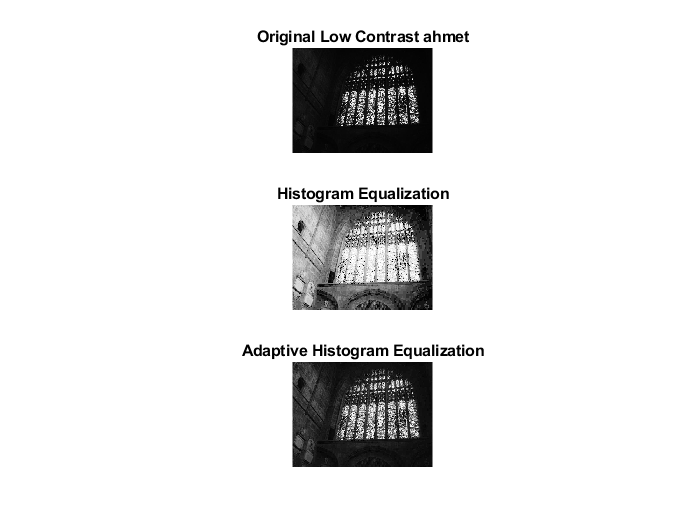

yoldas = imread('C:\Users\ahmet\Desktop\ahmetYOLDAS.jpg');
[rows, columns, ~] = size(yoldas);
if size(yoldas, 3) == 3
    yoldas = rgb2gray(yoldas);
end
normalizedahmet = double(yoldas) / 255;
histeqahmet = histeq(normalizedahmet);
adapthisteqahmet = adapthisteq(normalizedahmet);
figure;
subplot(3, 1, 1);
imshow(normalizedahmet);
title('Original Low Contrast ahmet');
subplot(3, 1, 2);
imshow(histeqahmet);
title('Histogram Equalization');
subplot(3, 1, 3);
imshow(adapthisteqahmet);
title('Adaptive Histogram Equalization');

Q5)

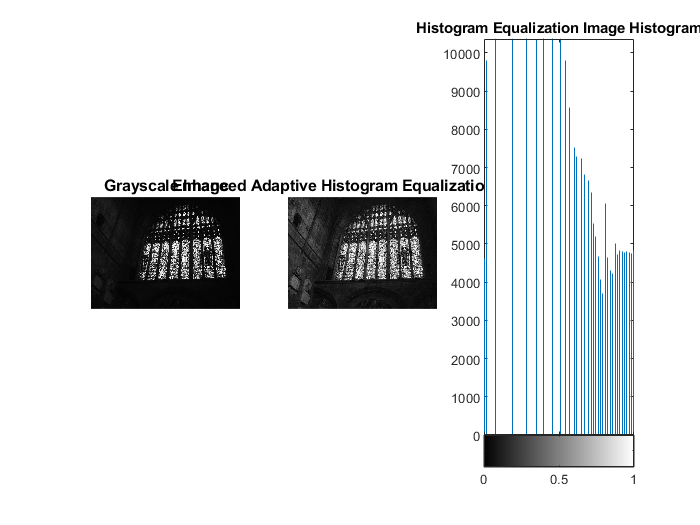

yoldas=imread('C:\Users\ahmet\Desktop\ahmetYOLDAS.jpg');
yoldas=rgb2gray(yoldas);
yoldas=im2double(yoldas);
A = histeq(yoldas);
subplot(1,3,1)
imshow(yoldas)
title('Grayscale ahmet','fontsize', [12])
subplot(1,3,2)
imshow(A)
title('Enhanced Histogram Equalization Method','fontsize',[12])
subplot(1,3,3)
imhist(A)
title('Histogram Equalization Image Histogram','fontsize',[10])
B = adapthisteq (yoldas);
subplot(1,3,1)
imshow(yoldas)
title('Grayscale Image','fontsize', [10])
subplot(1,3,2)
imshow(B)
title('Enhanced Adaptive Histogram Equalization Method')

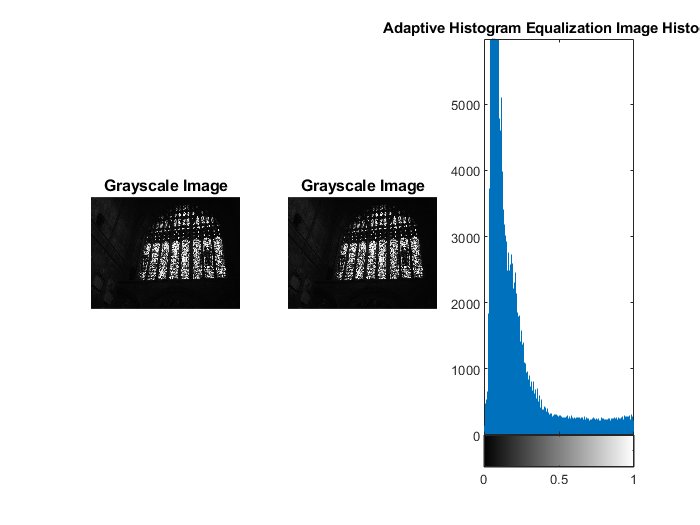

subplot(1,3,3)
imhist(B)
title('Adaptive Histogram Equalization Image Histogram')
A = histeq(yoldas); 
B = adapthisteq(yoldas);
subplot(1,3,2)
imshow(yoldas)
title('Grayscale Image','fontsize', [10])

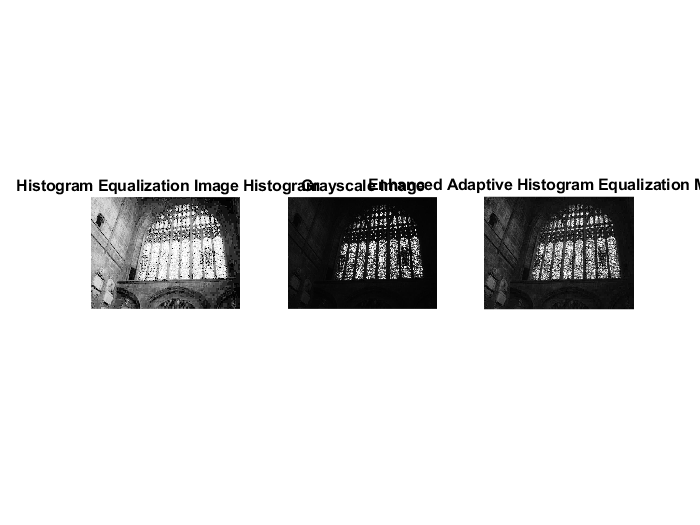

subplot(1,3,3)
imshow(B)
title('Enhanced Adaptive Histogram Equalization Method')
subplot(1,3,1)
imshow(A)
title(' Histogram Equalization Image Histogram')

Q6)

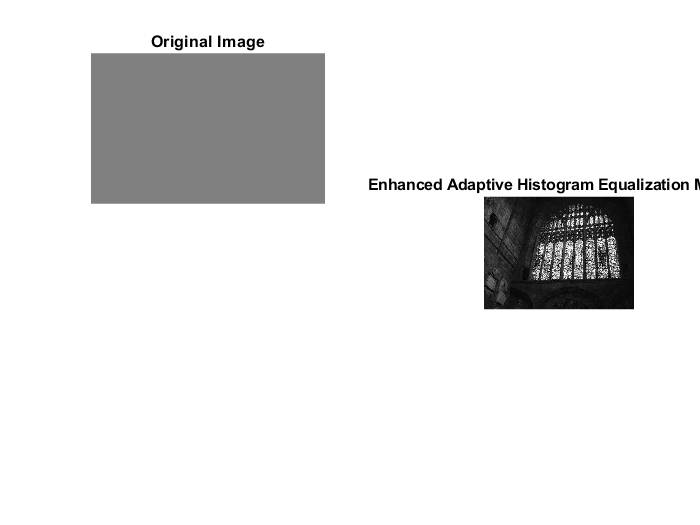

%ID 19050211052
ahmet = imread('C:\Users\ahmet\Desktop\ahmet.jpg');
ahmet = im2double(ahmet);
ahmet=rgb2gray(ahmet);
rows=180; 
columns=280;
ahmet_gray=zeros(rows,columns) + 0.5;
noise_1 = -0.22+ rand(rows,columns)*0.44;%add random values(noise) between -0.22 and +0.22 to every pixel of image
ahmet_gray_noise1 = ahmet_gray + noise_1;
noise_2 = -0.32+ rand(rows,columns)*0.64;%adding random values between -0.32 and +0.32
ahmet_gray_noise2 = ahmet_gray + noise_2;
subplot(2,2,1)
imshow(ahmet_gray)
title('Original Image','fontsize', [10])

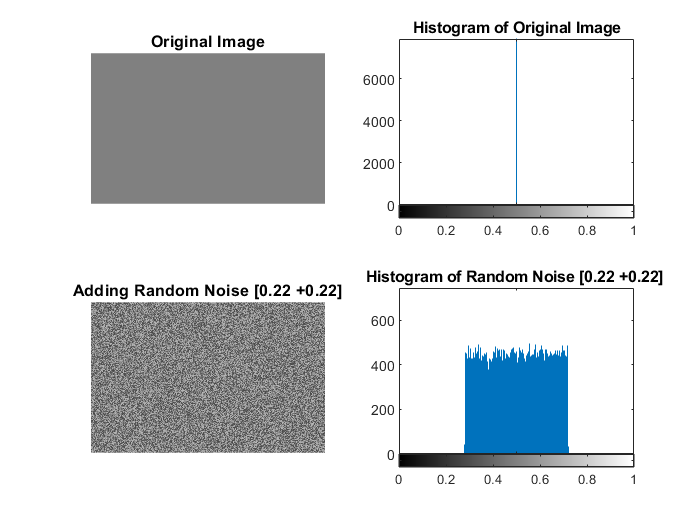

subplot(2,2,2)
imhist(ahmet_gray)
title('Histogram of Original Image','fontsize', [10])
subplot(2,2,3)
imshow(ahmet_gray_noise1)
title('Adding Random Noise [0.22 +0.22]','fontsize', [10])
subplot(2,2,4)
imhist(ahmet_gray_noise1)
title('Histogram of Random Noise [0.22 +0.22] ','fontsize', [10])

noise_1 = -0.22+ rand(rows,columns)*0.44;
ahmet_gray_noise1 = ahmet_gray + noise_1;
noise_2 = -0.32+ rand(rows,columns)*0.64;%adding random values between -0.32 and +0.32
ahmet_gray_noise2 = ahmet_gray + noise_2;
 
subplot(2,2,1)
imshow(ahmet_gray)
title('Original Image','fontsize',  [10])

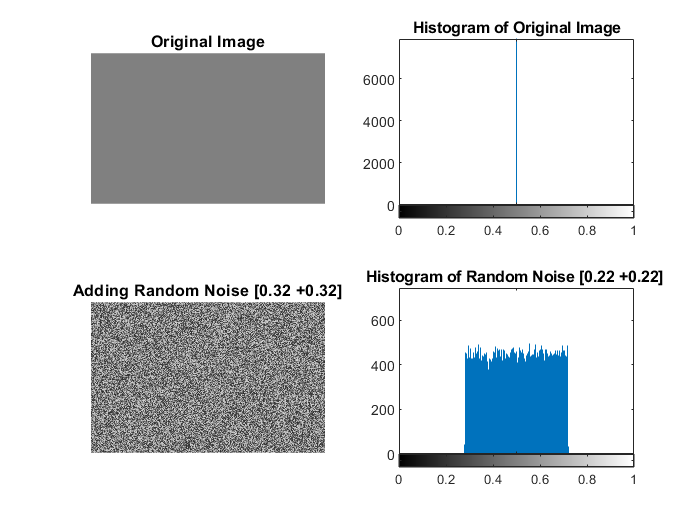

subplot(2,2,2)
imhist(ahmet_gray)
title('Histogram of Original Image','fontsize', [10])
subplot(2,2,3)
imshow(ahmet_gray_noise2)
title('Adding Random Noise [0.32 +0.32]','fontsize', [10])

subplot(2,2,4)
imhist(ahmet_gray_noise2)
title('Histogram of Random Noise [0.32 +0.32] ','fontsize', [10])






Q7)

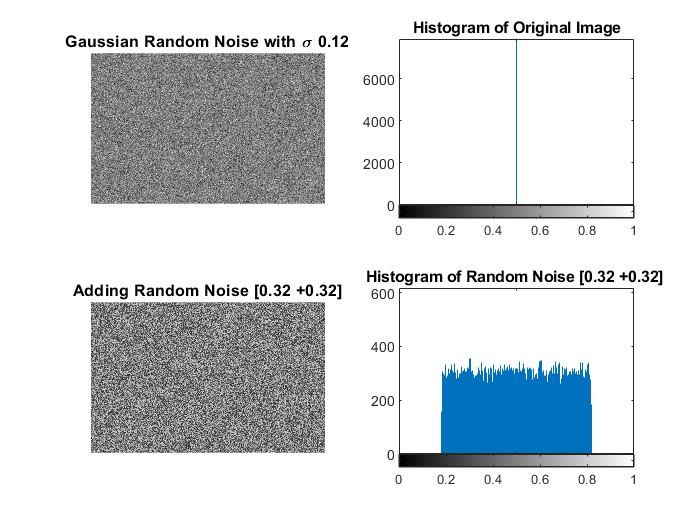

ahmet = imread('C:\Users\ahmet\Desktop\ahmet.jpg');
ahmet = im2double(ahmet);
ahmet=rgb2gray(ahmet);
rows=180; 
columns=280;
ahmet=zeros(rows,columns) + 0.5;
mu=0; 
sigma=0.12;
gnoise_1 = randn(rows,columns)*sigma;
 
sigma_2=0.22;
gnoise_2 = randn(rows,columns)*sigma_2;
 
gaussian_noise_1 = ahmet + gnoise_1;
gaussian_noise_2= ahmet + gnoise_2;
 
 
subplot(2,2,1)
imshow(gaussian_noise_1)
title('Gaussian Random Noise with \sigma 0.12','fontsize', [10])

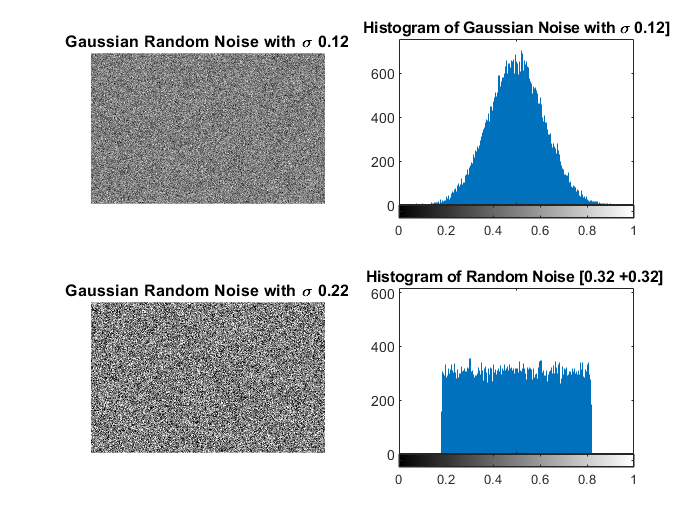

subplot(2,2,2) 
imhist(gaussian_noise_1)
title('Histogram of Gaussian Noise with \sigma 0.12]','fontsize', [10])
subplot(2,2,3)
imshow(gaussian_noise_2)
title('Gaussian Random Noise with \sigma 0.22','fontsize', [10])

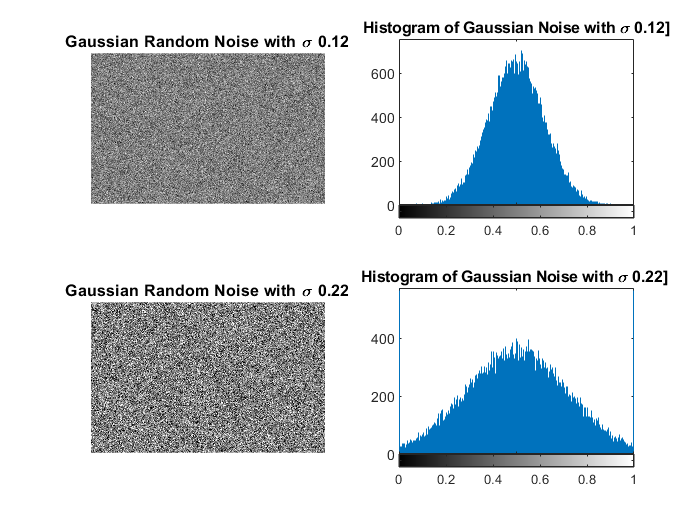

subplot(2,2,4)
imhist(gaussian_noise_2)
title('Histogram of Gaussian Noise with \sigma 0.22] ','fontsize', [10])

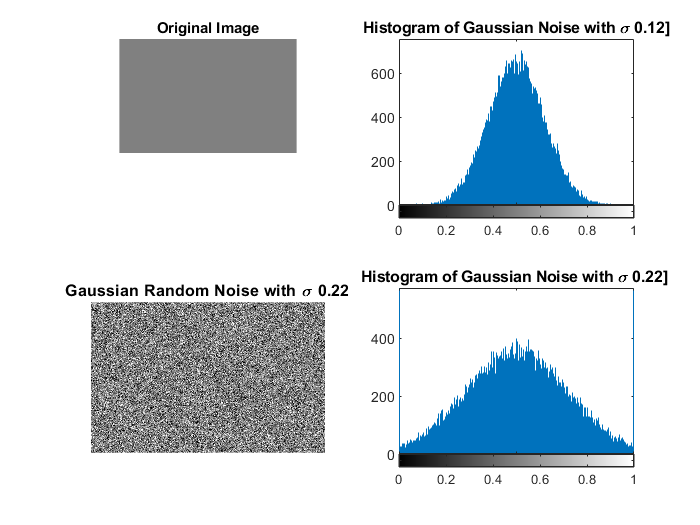

subplot(3,2,1)
imshow(ahmet)
title('Original Image','fontsize',  [10])

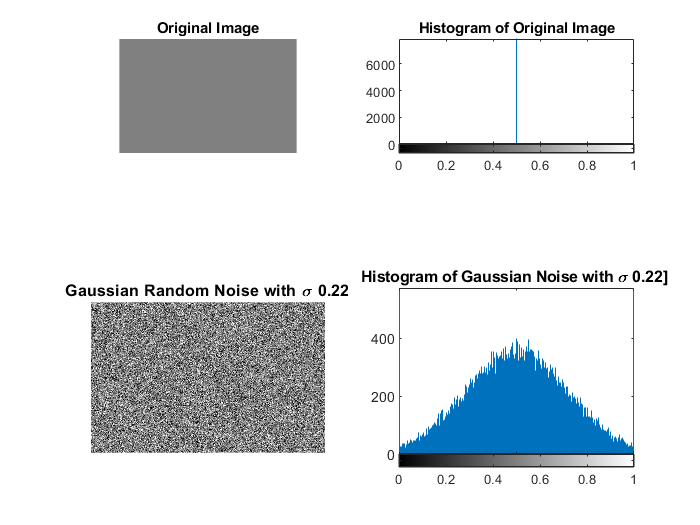

subplot(3,2,2)
imhist(ahmet)
title('Histogram of Original Image','fontsize', [10])

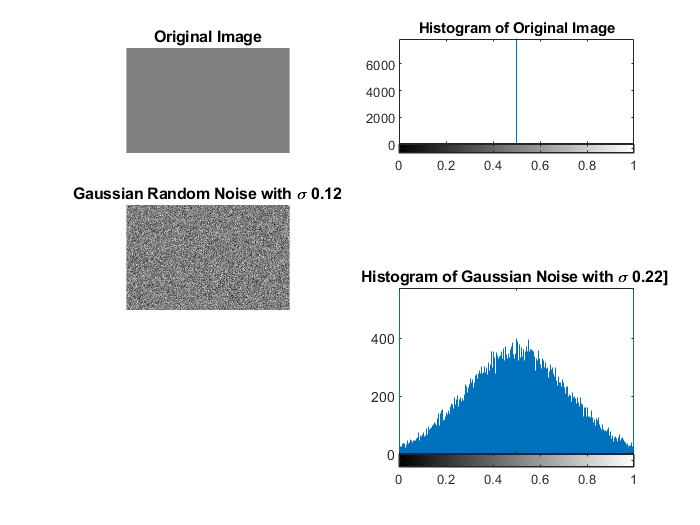

subplot(3,2,3)
imshow(gaussian_noise_1) 
title('Gaussian Random Noise with \sigma 0.12','fontsize', [10])

subplot(3,2,4)
imhist(gaussian_noise_1)
title('Histogram of Gaussian Noise with \sigma 0.12]','fontsize', [10])
subplot(3,2,5)
imshow(gaussian_noise_2)
title('Gaussian Random Noise with \sigma 0.22','fontsize', [10])
subplot(3,2,6)
imhist(gaussian_noise_2)
title('Histogram of Gaussian Noise with \sigma 0.22] ','fontsize', [10])